## Lab 2 : Probability, Distributions, and Statistical Questions

Kuan-Wei Lee

**(add partner) **Megan Miyasaki 

Student#: 1663855

Problem 1

A.

The code below take the average of Poisson distribution over 5 days and 10 days(this is averaging the distribution of the background over 5 days and 10 days).

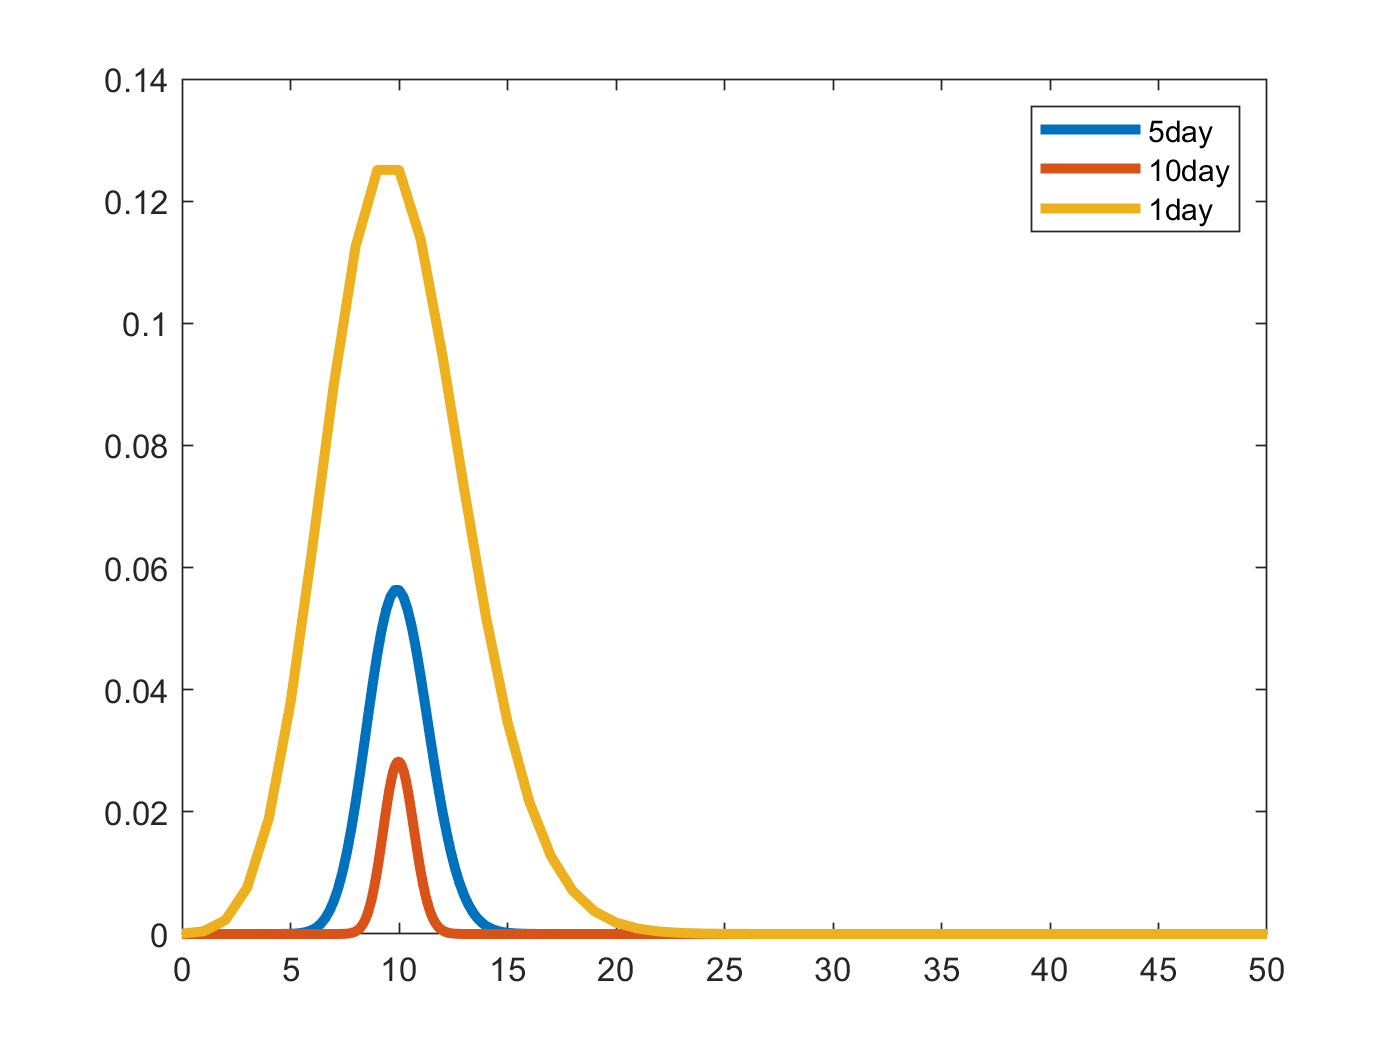

clear all
close all
clc

pd = makedist('Poisson','Lambda',10);
dx = 1;
x = 0:dx:50;
d1 = 5;
d2 = 20; % do you mean 10 for d2? if its over 5 and 10 days?
Poisson = pdf(pd,x);
Poisson = Poisson./sum(Poisson);
res = conv(Poisson,Poisson);
for i = 1:(d1-2)
    prob1 = conv(res,Poisson);
    res = prob1;
end

res2 = conv(Poisson,Poisson);
for j = 1:(d2-2)
    prob2 = conv(res2,Poisson);
    res2 = prob2;
end
x2 = min(x):dx/d1:max(x);
x3 = min(x):dx/d2:max(x);
plot(x2,prob1,'LineWidth',3)
hold on
plot(x3,prob2,'LineWidth',3)
xlim([min(x) max(x)])
plot(x,Poisson,'LineWidth',3)
legend('5day','10day','1day')
xlim([min(x) 50])
hold off

% possibly add a title to the graph so we know what is going on?
% title('probability distribution of background over x days')

As the distribution is averaged over more days, the distribution become narrower and the "tail end" has much smaller values and become less important. 

**comment: if possible maybe mention how the average should go further out as you sum over more days. **

B.

The action that we take to find the sum of Poisson distribution is by taking the convolution of the Poisson distribution with itself. **please explain a little more if possible? **

The convolution in the integral form is : $f\ast g=\int_{-\infty }^{+\infty } f\left(x\right)g\left(t-x\right)\textrm{dx}$. If f and g are the same function, then the result of the convolution is still the same function but with different distribution from the original distribution function. 

C.

In this section, the distribution of averaging over 5 days, 10days, 15 days, and 20 days were calculated. The plot suggests that when averaging over more days, the Poisson distribution becomes narrower and looks more like a Gaussian distribution.


clear vars
clc

pd = makedist('Poisson','Lambda',3);
dx = 1;
x = 0:dx:50;
Poisson = pdf(pd,x);
Poisson = Poisson./sum(Poisson);
D = [5 10 15 20]

D =      5    10    15    20


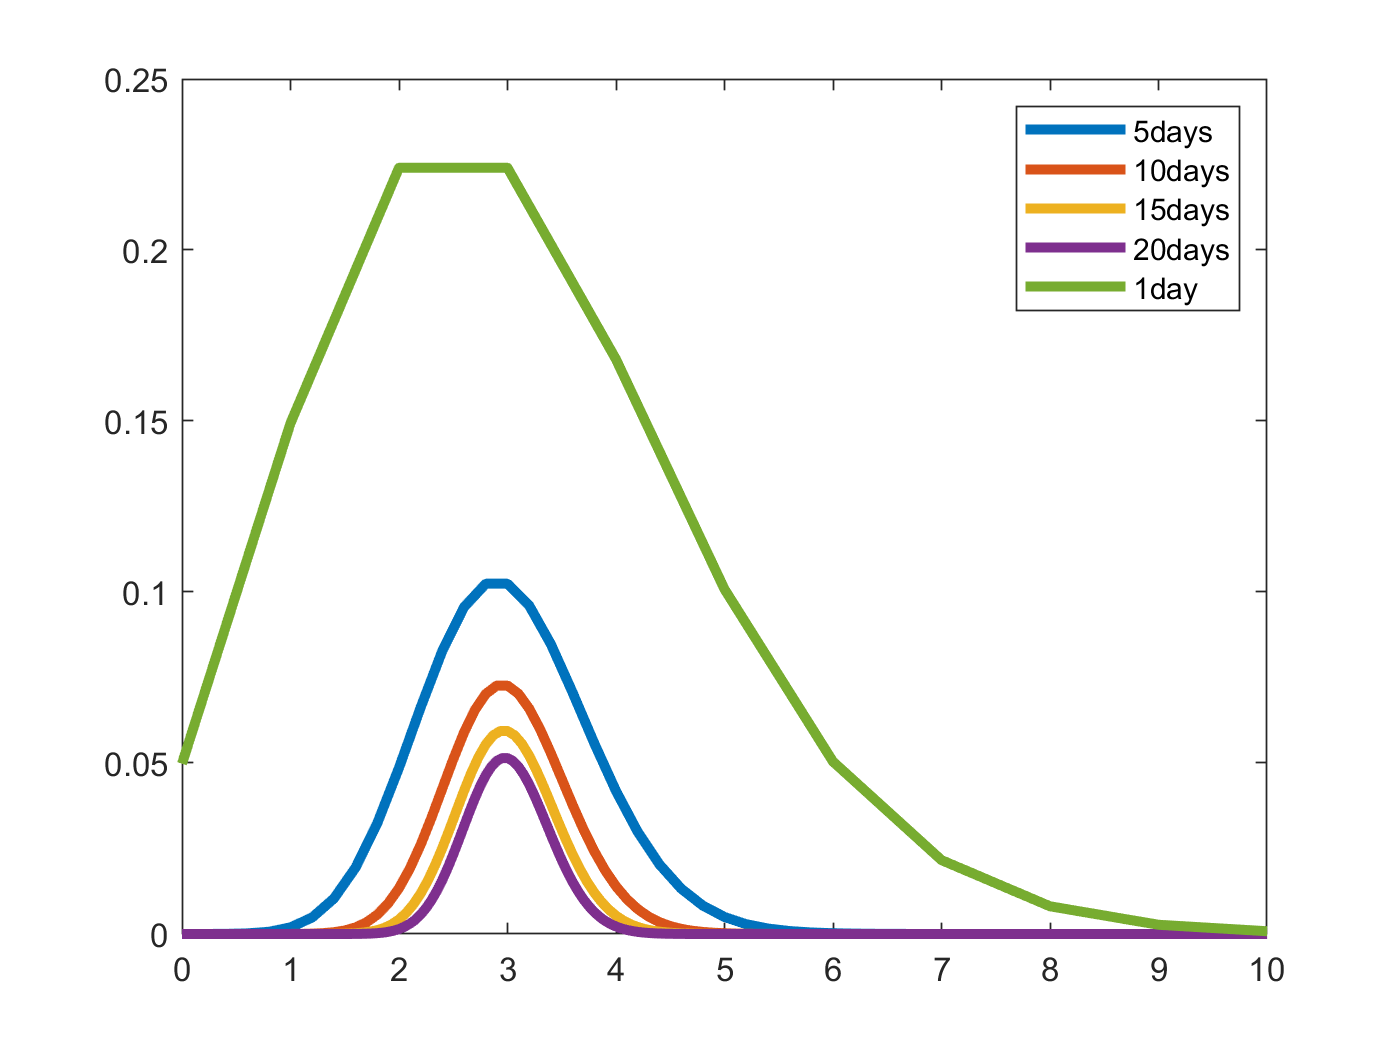


for i = 1:length(D)
    res = Poisson;
    for j = 1:D(i)-1
        
        Prob_d = conv(res,Poisson);
        res = Prob_d;
        
    end
    x_new = min(x):dx/D(i):max(x);
    plot(x_new,Prob_d,'LineWidth',3)
    hold on
end
plot(x,Poisson,'LineWidth',3)
xlim([min(x) 10])
legend('5days','10days','15days','20days','1day')
hold off

%same comment to all your graphs possible add a title to tell someone what
%is going on in this graph but looks good, and it proves that it becomes
%more guassian as you said 

D.

According to the central limit theorem, as the sample size of a distribution goes up very high, the distribution approches to Gaussian. To calculate the probability of getting a signal that is as signal like or more than the signal, we need to integrate the distribution from the point of the signal (Y) to infinity.  After convolved for 10 times, the distribution will be different from the original Poisson distributio. However, we can approximate the distribution with a Gaussian distribution. According to the centrial limit theorem, a Poisson distribution Poiss($\lambda$) can be approximate by a Gaussian distribution with mean = $N\lambda$, and $\sigma =\sqrt{N\lambda }$, where N is the sample size of Poisson distribution

The code below demonstrate that the Poisson distribution can indeed be approximated by a Normal distribution when the sample size is large. A Poisson distribution with lambda = 3 is chosen. The Poisson distribution is convolved to itself for 20 times (this means that the background emission is averaged over 20 days). The distribution we get after convolving Poisson for 20 times can be approximated by a Gaussian distribution with $\mu =20*3,\sigma =\sqrt{3*20}$. (The sample size of the Poisson distribution is 20, and it turns out to be large enough to be approximated by the Gaussian distribution)

The average gamma rays emission of the source Y is chosen to be 5

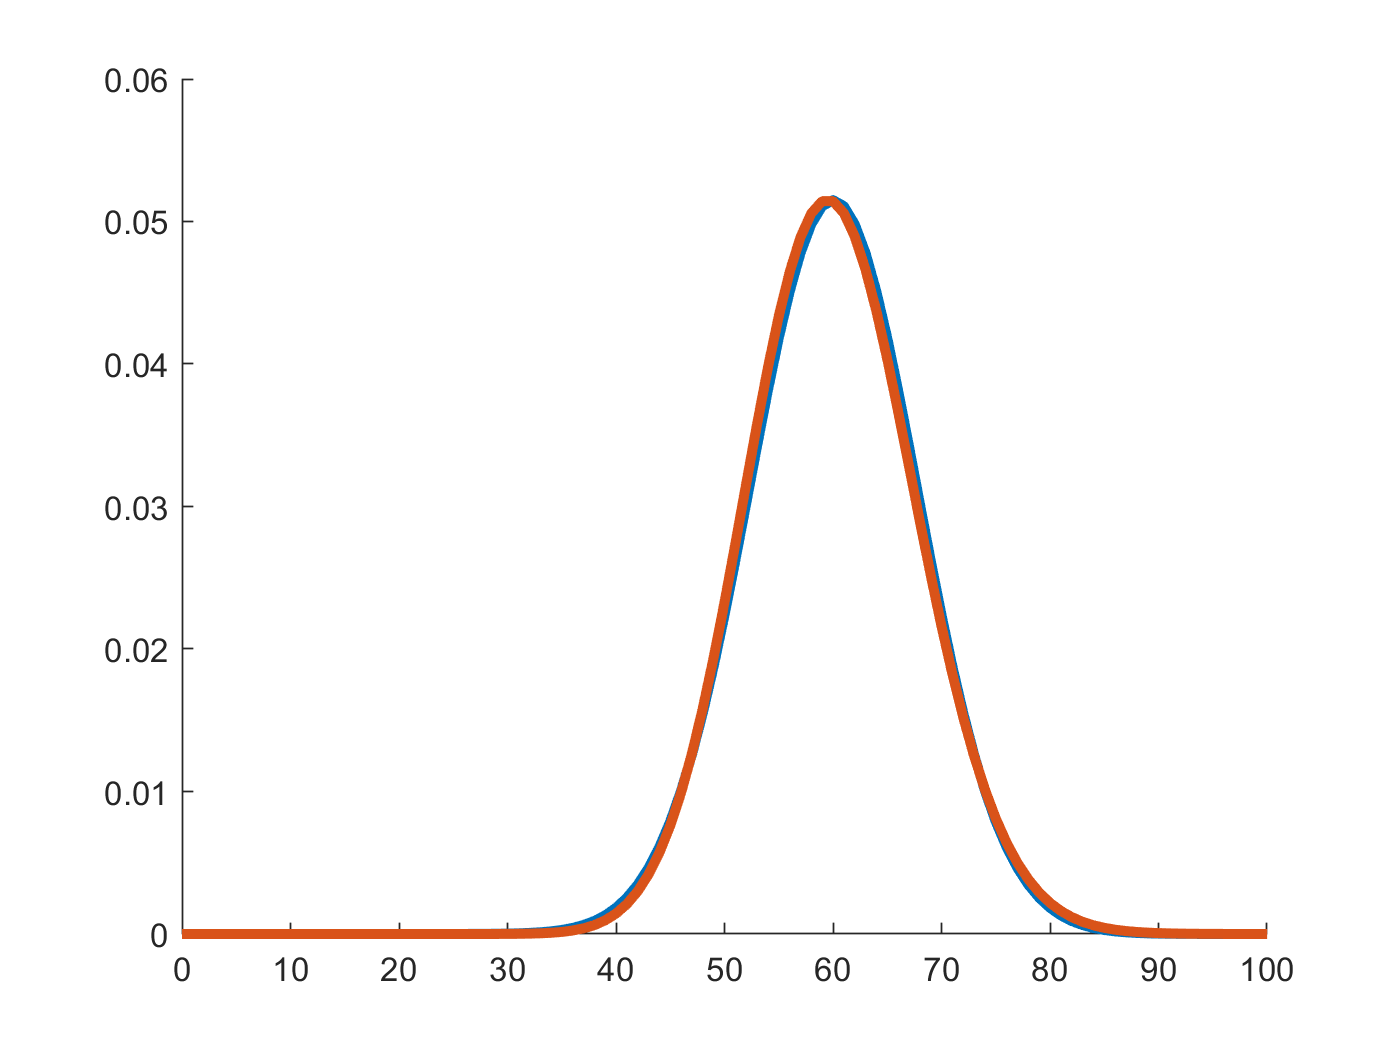

close all


pd = makedist('Poisson','Lambda',3);
dx = 1;
x = 0:dx:50;
Poisson = pdf(pd,x);
Poisson = Poisson./sum(Poisson);
pd = makedist('Normal','mu',3*20,'sigma',sqrt(3*20));
x = 0:1:1000;
Gaussian = pdf(pd,x);
hold on
plot(x,Gaussian,'LineWidth',3)
plot(x,Prob_d,'LineWidth',3)
xlim([0 100])
hold off

%possibly change the lines a bit so we can see the og or add a legend so we
%know there are two on this graph and that they sit well on each other. 

Poisson distribution after convolved 20 times and the Gaussian distribution that approximate the Poisson distribution was plotted. Two curves are very close. It means that the Gaussian distribution was a good approximation. 

%Find the probability of getting signal that is as signal like or more than
%the signal
Y = 5;
P = 1-normcdf(Y*20,60,sqrt(60));
%Calculate the sigma of Y
S = norminv(1-P,0,1);

Sigma of the signal Y*20 is 5.164. This sigma suggests that the probability of measuring Y*20 gamma rays over 20 days to be a false signal from the background is about 1.2*${10}^{-7} \ldotp$

2.

Pick a skewed continuous distribtuion, such as a Rayleigh, that describes your background over some observing interval.

A) Show how the distribution changes as you average over more observing intervals.

B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?

A.

Rayleigh distribution was chosen to examin how the distribution changes as it is averaged over more observing intervals.

Rayleigh distribution wit b = 5 (parameter) was averaged over observation intervals of 5, 10, 15, 20.

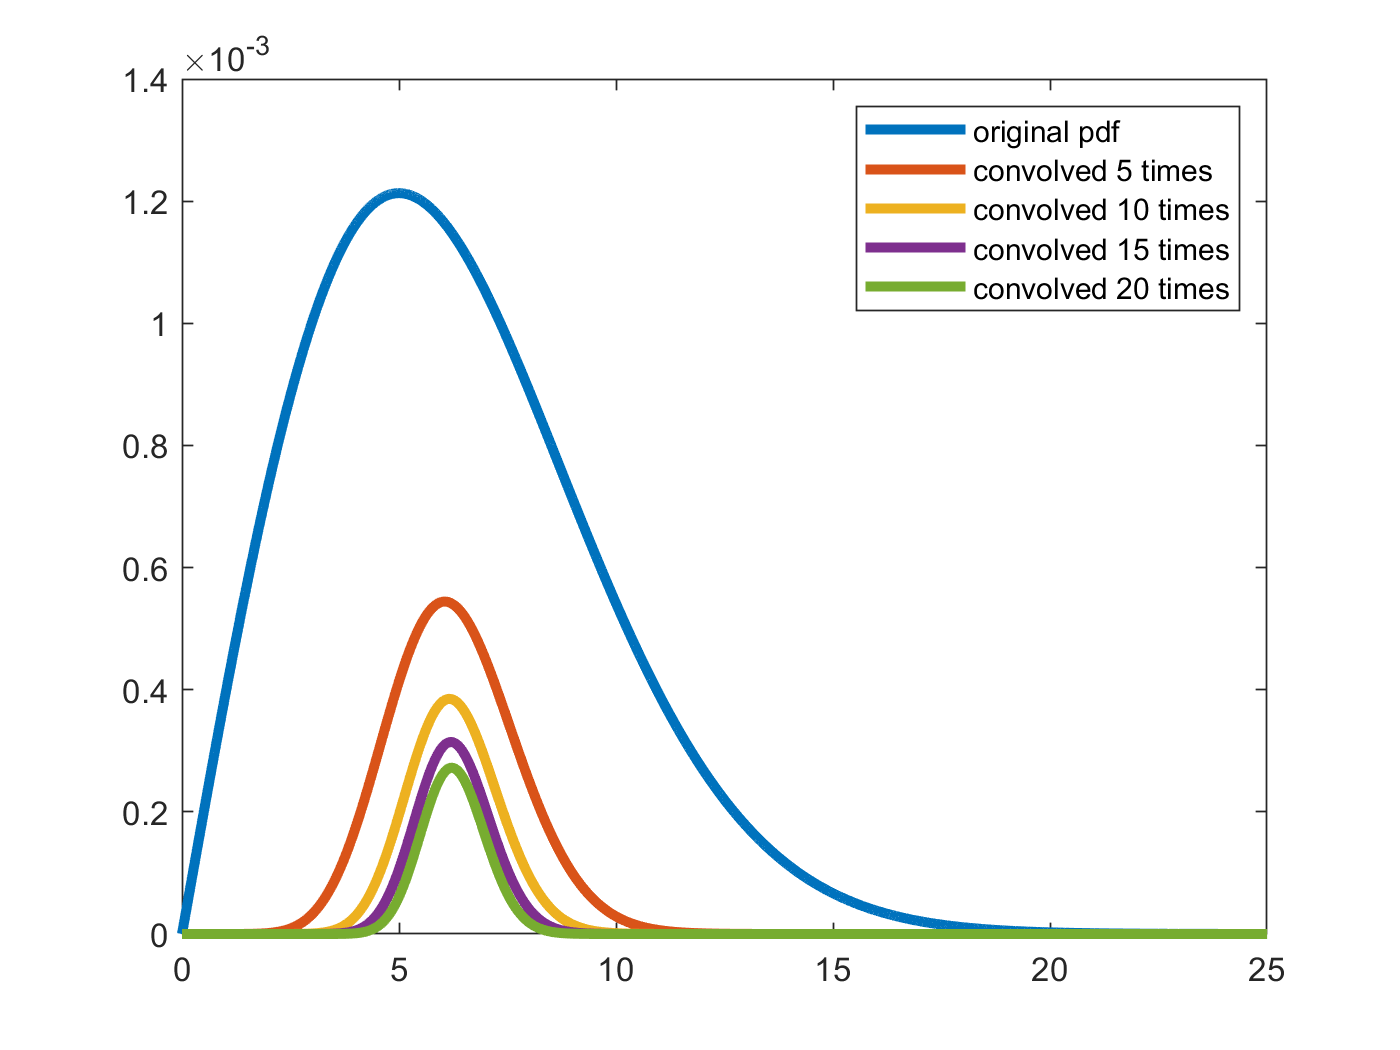

clear all
close all
clc

pd = makedist('Rayleigh','b',5);
dx = 0.01;
x = 0:dx:50;
Rayleigh = pdf(pd,x);
Rayleigh = Rayleigh./sum(Rayleigh);

plot(x,Rayleigh,'LineWidth',3)
hold on
C = [5 10 15 20];
for i = 1:length(C)
    res = Rayleigh;
    for j = 1:C(i)-1
        
        Prob_d = conv(res,Rayleigh);
        res = Prob_d;
        
    end
    x_new = linspace(min(x),max(x),length(Prob_d));
    plot(x_new,Prob_d,'LineWidth',3)
    hold on
end
legend('original pdf','convolved 5 times','convolved 10 times','convolved 15 times','convolved 20 times')
xlim([0 25])
hold off

B.

The graph shows that as the Rayleigh distribution is averaged more observing period, the distribution looks more and more like a Gaussian. This is consistent with the central limit theorem because the central limit theorem states that as the sample size of a distribution gets large, that distribution looks like a Gaussian.

According to the graph, Rayleigh distribution almost stop changing its shape after averaging over 10 observing period.

3.

The discovery of optical/infra-red counterparts of Neutron star mergers initially detected with gravity-waves is one of the great discoverys in the last few years ([wikipedia](https://en.wikipedia.org/wiki/GW170817), [scientific paper](https://arxiv.org/abs/1710.05833)), and has ushered in the age of "multi-messenger astrophysics." The science that can be done by matching a gravity-wave signal (directly measures the mass of the neutron stars and their distance) with the optical emisson (redshift, nuclear astrophysics of the resulting explosion) is *staggering*. Lots of science from how the heaviest elements are formed to constraints on Dark Energy.

We're going to explore one of the analysis questions that comes up when looking for the optical counterparts (a new optical source) of a gravity wave signal. For this problem let's assume that we are using an optical telescope with a thermal noise background from the CCD (dark current, particularly an issue with older CCDs and/or infra-red CCDs). After flat-fielding, the background appears as a zero-mean Gaussian with constant width over the image.

**Version 1**

You have an alert from [LIGO](https://www.ligo.caltech.edu/) that is also seen in with the X-ray/ultra-violet satellite [SWIFT](https://swift.gsfc.nasa.gov/). SWIFT gives you a very precise location, so you take an image of that part of the sky. But because of SWIFT's accuracy, you know which pixel in your image to look for a counterpart in.

A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?

A Gaussain distribution with mu=10, sigma=4 was chosen.

The signal Y is chosen to be 15.

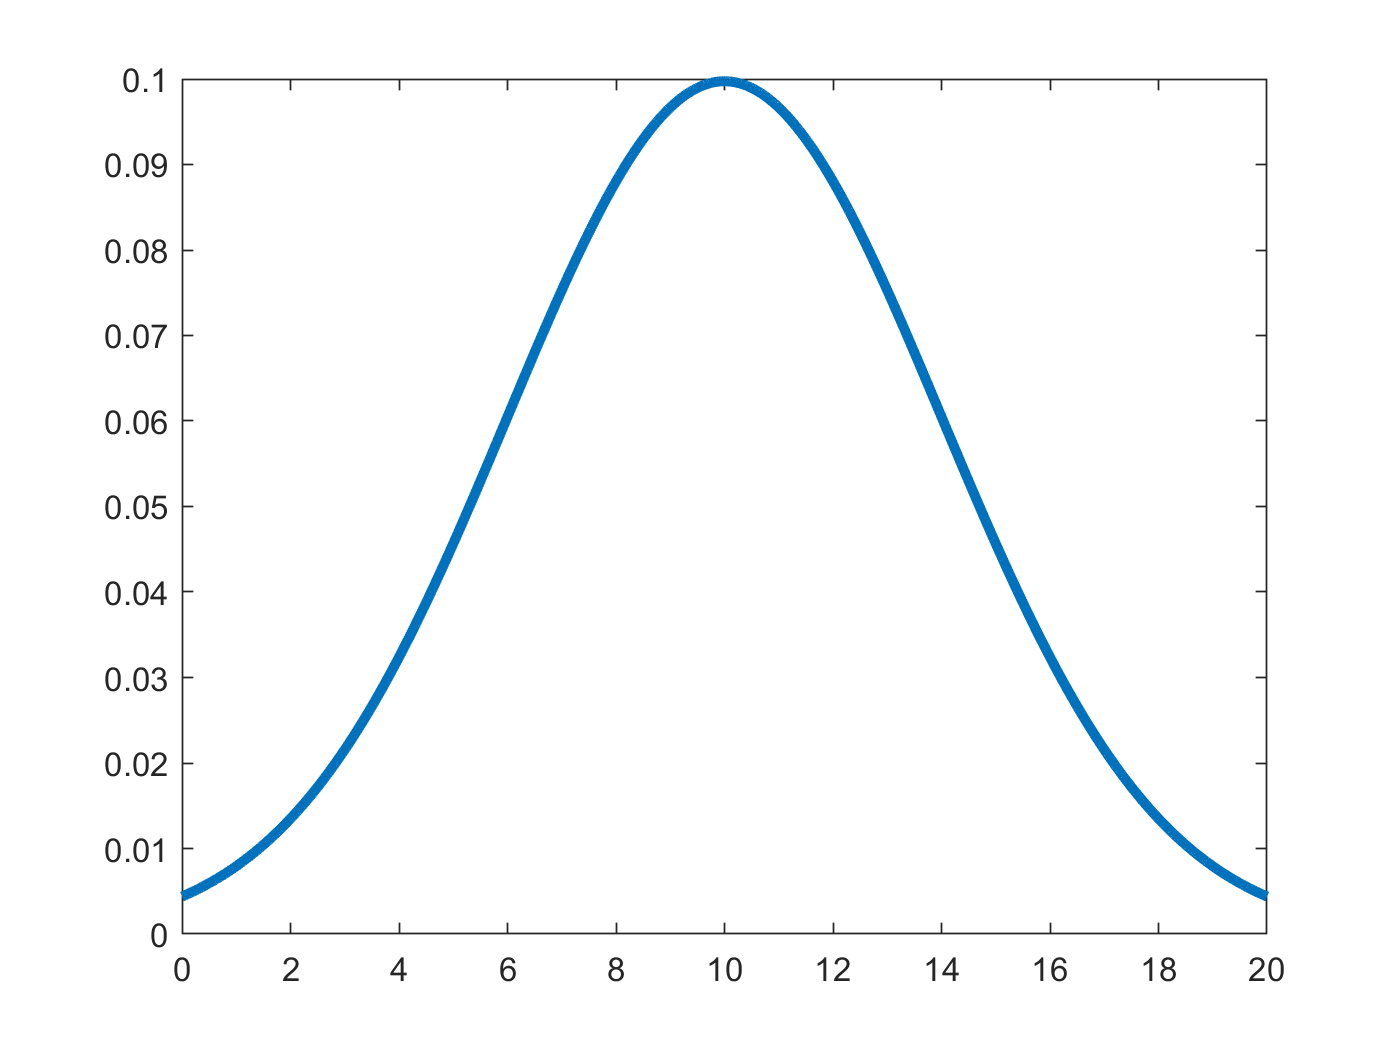

clear all
close all
clc

mu = 10;
sigma = 4;
pd = makedist('Normal','mu',mu,'sigma',sigma);
x = 0:0.01:50;
Gaussian = pdf(pd,x);
plot(x,Gaussian,'LineWidth',3)
xlim([0 20])

To determin the significance of the signal Y=15, we must calculate its sigma. 

The code below calculate the sigma of signal Y. It calculate the probability of getting a reading that is equal to or greater than Y because more reading is more signal like.

With the probobility calculated, I then calculate the sigma assuming the background distribution is Gaussian (which is indeed Gaussian).

Y = 15;
%Probability of getting a reading that is equal to or greater than Y from
%the background
P = 1-normcdf(Y,mu,sigma);
%Calculate sigma with the probability that was found from the last step
S = norminv(1-P,0,1);

After the calculation, the sigma of the signal Y is found to be 1.25. This is not significant enough to be claimed a discovery because normally a sigma of 5 is desirable.

**Comment: looks good, possibly give what a signicancy of 5 sigma might be to some one who does not know its value, i think its 1 in 3.5 million. **

**Version 2**

You have an alert from LIGO, but no associated detection from SWIFT. This could be because it is a black hole-black hole merger, a black hole-neutron star merger (neither seem to emit X-rays or UV light), or it could because SWIFT was indisposed at the time (wrong side of the earth in its orbit). Whatever the cause, you know what region of the sky to look in, but not which pixel.

B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*Clearly* state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)

C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.

B.

We first divide the 10k pixels into 100 regions with 100 pixels in each region. Assuming the distribution in each region has a Gaussian distribution. 

After we made the assumption. The question is: what is the distribution of the background when averaging the distribution over 100 regions?

The code below calculate the backgroundl distribution average over 100 intervals. 

The background distribution was assumed to be a lognormal distribution with mu = 10, sigma = 4.

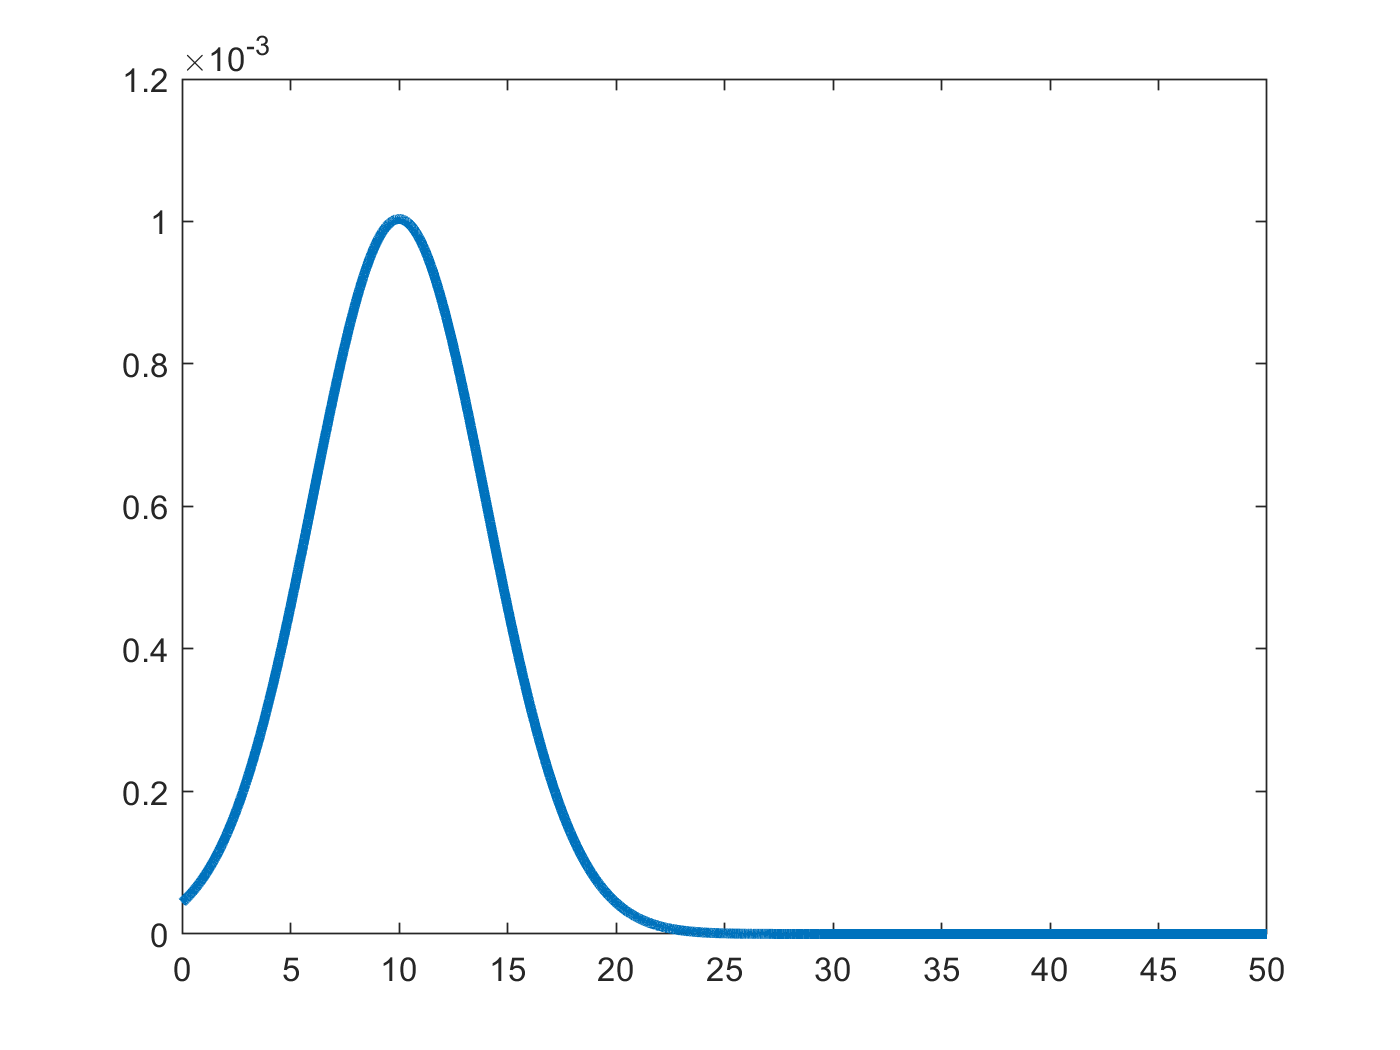

clear all
close all
clc

mu = 10;
sigma = 4;
pd = makedist('Normal','mu',mu,'sigma',sigma);
x = 0:0.01:50;
Gaussian = pdf(pd,x);
Gaussian = Gaussian./sum(Gaussian);
plot(x,Gaussian,'LineWidth',3)

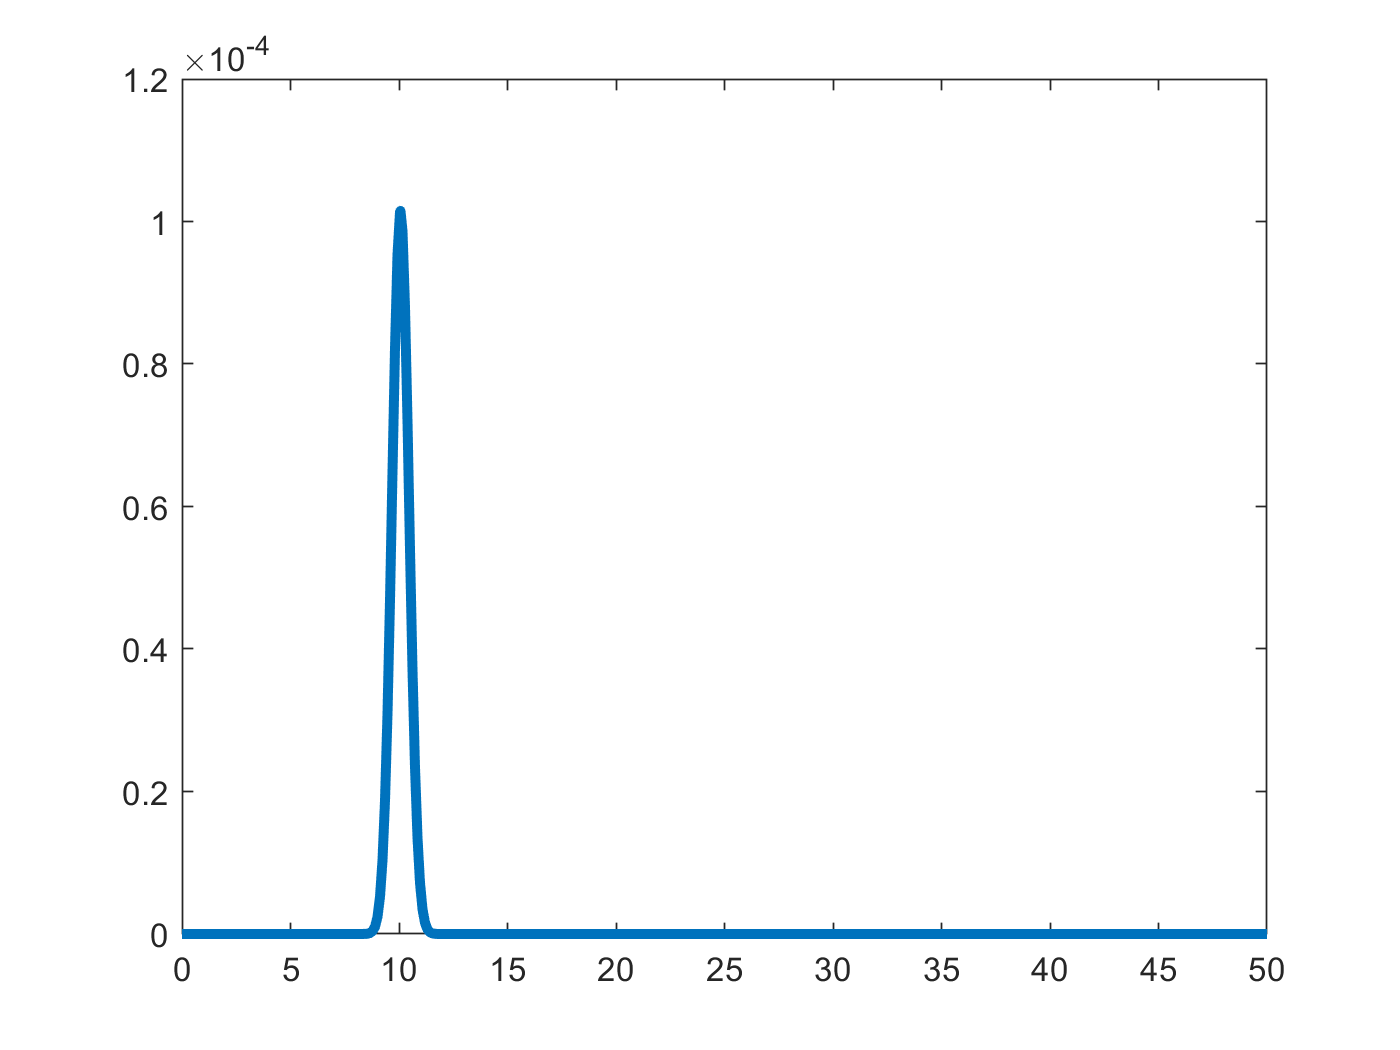

% if possible can you compare it to the other graph you made in version one
% so we can see the differnce?

%Average the background distribution over 20 regions of pixels
res = Gaussian;
for i = 1:100
    Prob_d = conv(res,Gaussian);
    res = Prob_d;
end
Gaussian_avg = Prob_d;
x_new = linspace(min(x),max(x),length(Prob_d));
x_new2 = linspace(0,max(x)*100,length(Prob_d));
plot(x_new,Gaussian_avg,'LineWidth',3)

After the background distribution is averaged over 100 intervals, it becomes like a Gaussian. 

To find the significance of the signal Y=15, we need to approximate the distribution we found by averaging over 100 intervals. 

Since the original distribution is a Gaussian distribution, finding the new Gaussian distribution that is produced by convolving the original Gaussian by 100 times is not very hard.

If Z is a Gaussian distribution where Z =X+Y and both X and Y are Gaussian distribution. The Z is a Gaussian distribution where $\mu_Z =\mu_{x+\mu_y } ,{\sigma_Z }^2 =\sigma_x^2 +\sigma_y^2$

The Gaussian distribution we get after convolving the Gaussian distribution with itself for 100 times is a Gaussian distribution with $\mu_{\textrm{new}} =\mu_{\textrm{old}} *100,\;\sigma_{\textrm{new}}^2 =\sigma_{\textrm{old}}^2 *100$

mean = 10*100;
sigma = sqrt(4^2*100);

The Gaussian that approximate the averaged lognormal distribution has mean = 10.0687, sigma = 0.3891

C.

We can use this Gaussia distribution to evaluate the significance of the signal Y.

We can find the probability of the back ground giving us a reading that is equal to or greater than the signal Y=15 and then find the sigma.

mu = mean;

Y = 15*100;
P = 1-normcdf(Y,mu,sigma);
S = norminv(1-P,0,1);


In the end, sigma of Y is found to be infinitly big. This is because we averaged the original Gaussian distribution for many times and the distribution get "squeezed". The probability of getting a reading equal to or greater than Y from a background distribution averaged over 100 times is extremly small.

4.

The statistical issue we were exploring in the previous problem is called a **trials factor** (sometimes known as a look-elsewhere effect). This is an important effect, as if you search through a million locations, you would expect to se ~1 one in a million event. However, it is also often over estimated how big an impact this makes on the sensitivity of a search. So in this part of the lab we are going to invert the problem.

Let us again assume we have a Gaussian background (same parameters as Problem 3).

A) Calculate the signal required for a 5-sigma detection in Version 1

B) Calculate the signal required for a 5-sigma detection in Version 2

C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.

D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?

Extra credit: If you had a different distribution shape (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.

A.

The code below calculate the signal required for a 5-sigma detection in Version 1:

clear vars P
mu1 = 10;
sigma1 = 4;
P = normcdf(5,0,1);
Signal1 = norminv(P,mu1,sigma1);

The signal required for a 5-sigma detection is 30.0687 in version 1.

B.

The code below calculate the signal required for a 5-sigma detection in Version 2:

clear vars P
P = normcdf(5,0,1);
Signal2 = norminv(P,mean,sigma)/100;

The signal required for a 5-sigma detection is 12 in version 2. This is about 2.5 times smaller the signal required in version 1.

C. 

According to the results from A and B, the signal required for a 5-sigma deteiction will be much smaller when the trial factor is 10k. If the trial factor is 10K, it means that we convolve the Gaussian distribution for 10000 times and it will make the Gaussian distribution very narrow. For a very narrow Gaussian distribution, it does not require a very strong signal to pass the 5-sigma threshold.

The result from A and B shows that when the trial factor is 100, the threshold goes down by a factor of 2.5. If trial factor is 10000, the thrshold will go down even more. 

D.

clear vars mean sigma
mean = 10*10000;
sigma = sqrt(4^2*10000);

clear vars P
P = normcdf(5,0,1);
Signal3 = norminv(P,mean,sigma)/10000;

When the trial factor is increased from 100 to 10000, the thrshold for 5-sigma detection goes from 12 to 10.2.

Compare to the decrease of threshold when changing the trial factor from 1 to 100, the decrease of thrshold by changing trial factor from 100 to 10000 was smaller. 

**overall looks good! just add some titles to the graph so if some one were to skim thru they would know what each graph is about, code looks solid and explantion are quite detailed! - megan **